This script serves to perform the required calibration needed to convert the radar permittivity to pseudoRAW values that allow us to use the TEROS 12 calibration process for various soil types.

c=299792458;                    % Speed of light (m/s)
resolution = 0.003790984152165; % Range resolution (m)

fprintf("Ground truth data stored in \n" + ...
    "https://docs.google.com/spreadsheets/d/1K78VeHg" + ...
    "P5uEu7g3LeU7YA1ABJxbuOkrdziNVeoTXbkk/edit?usp=" + ...
    "sharing");

Ground truth data stored in 
https://docs.google.com/spreadsheets/d/1K78VeHgP5uEu7g3LeU7YA1ABJxbuOkrdziNVeoTXbkk/edit?usp=sharing


runName = {};
radarPermittivity = [];
expectedRAW = [];

% ====================
databaseName = '/data/DryRun';
fprintf("Processing %s ...\n", databaseName)

Processing /data/DryRun ...



dryRunResults = run_dual_tag_dataset(databaseName, 80, 105, false);
averageRangeBinDifference = mean(dryRunResults{:, 6});

distance = 2/39.37;                         % Distance between tags (m)
t = ((averageRangeBinDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = 1946.07;                        % Taken from TEROS sensor readings

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity(end+1) = radar_perm;
expectedRAW(end+1) = TEROS_raw;
% ====================


% Final table of results
results = table(transpose(runName), transpose(radarPermittivity), transpose(expectedRAW), ...
    'VariableNames', {'Run Name', 'Radar Permitivvity', 'Expected Raw'});

disp(results)

        Run Name        Radar Permitivvity    Expected Raw
    ________________    __________________    ____________

    {'/data/DryRun'}          91.242             1946.1   




permittivity2raw = polyfit(radarPermittivity, expectedRAW, 3);

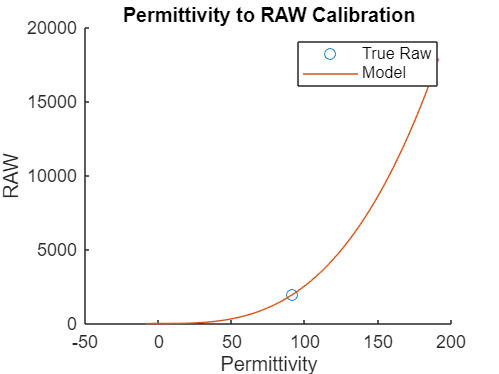


figure(1)
scatter(radarPermittivity, expectedRAW)
hold on
radarPermittivityPoints = linspace(min(radarPermittivity) - 100, max(radarPermittivity) + 100, 100);
plot(radarPermittivityPoints, polyval(permittivity2raw, radarPermittivityPoints))
legend(["True Raw", "Model"])
xlabel("Permittivity")
ylabel("RAW")
title("Permittivity to RAW Calibration")